# Interpolare Lagrange

## Aproximarea radicalului folosind interpolarea clasica Lagrange

nodes=[100 121 81 144];
values=[10 11 9 12];
L=lagrange_sym(nodes,values)

$$L = \frac{x^{3}}{2018940}-\frac{37\,x^{2}}{134596}+\frac{91027\,x}{1009470}+\frac{9900}{3059}$$

val=double(subs(L,115))

val =           10.7240482629499


err1=abs(val-sqrt(115))  % eroarea fata de valoarea reala

err1 =       0.000242968186256576


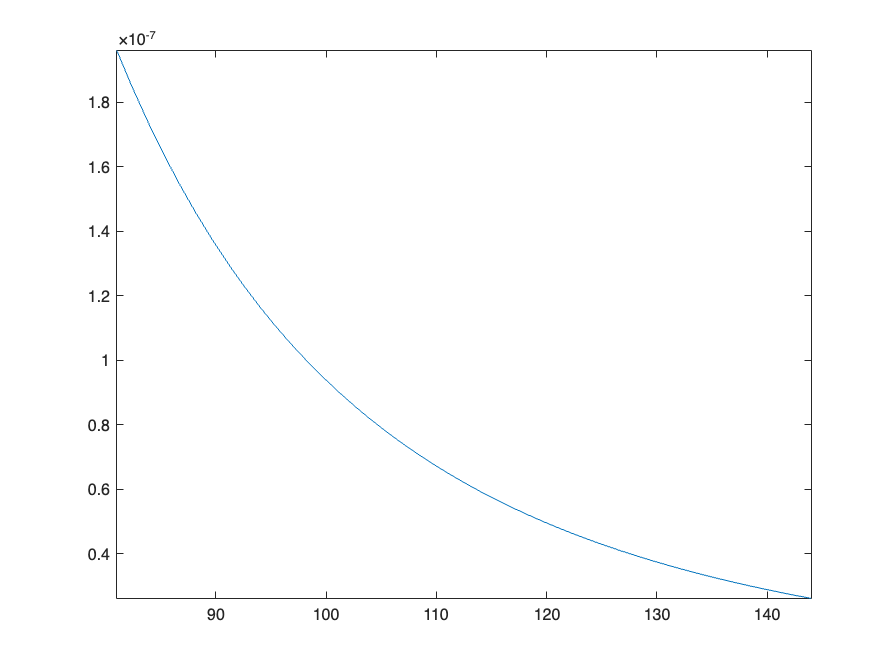

syms x;
f4 = diff(sqrt(x),4);
fplot(abs(f4), [81 144])  % se observa ca punctul de minim pentru |f^(4)| este in x = 81

err2=double(prod(115-nodes)/factorial(sym(4))*subs(abs(f4),81))  % restul Lagrange (eroarea estimata)

err2 =       0.000724739434857303


## Aproximarea folosind interpolarea Lagrange cu metoda baricentrica

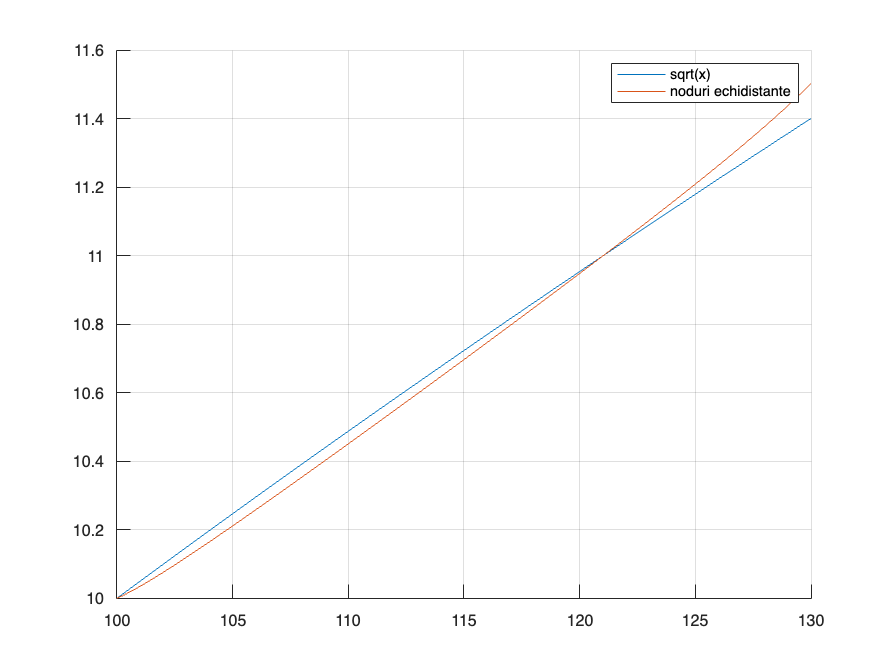

clf; hold on; grid on;
X=linspace(100,130,500);

val_real=sqrt(X);
values=sqrt(nodes);
val_echidistante=LagrangeBary(nodes, values, X, 'echidistante');
plot(X, val_real)
plot(X, val_echidistante)

legend('sqrt(x)', 'noduri echidistante')

## Runge

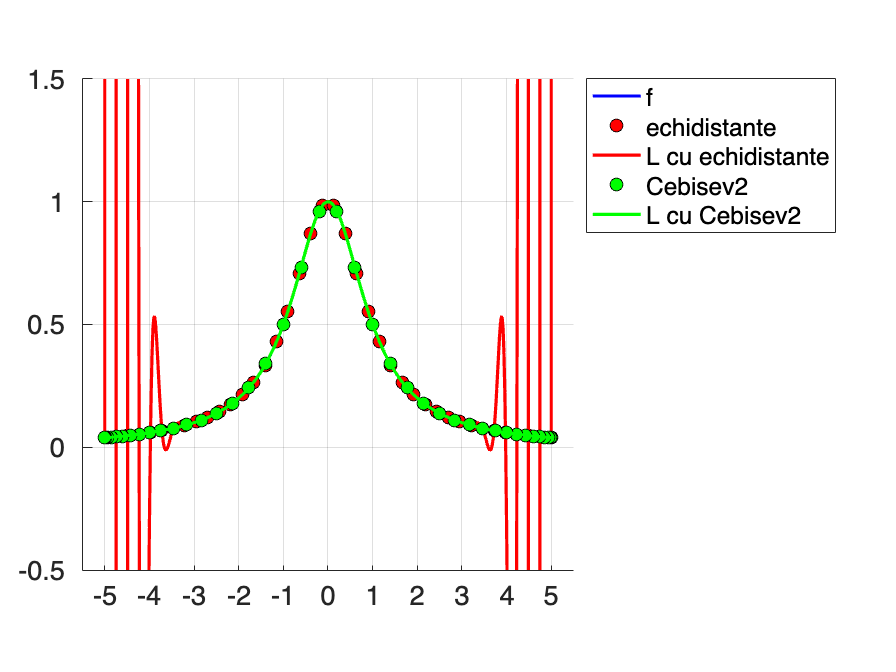

Runge_exemplu